### Step 0 加载并绘制原始mri图像

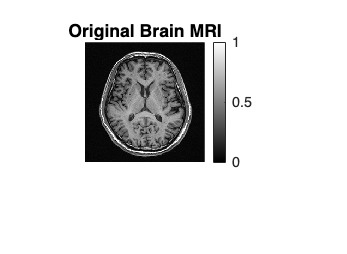

data = load('../data/Lab4_2025_MRI.mat');
variableNames = fieldnames(data);
mriData = data.(variableNames{1}); 
mriData = mat2gray(mriData);

figure;
imshow(mriData, []);
colormap gray;
colorbar;
title('Original Brain MRI');

## Project 3 restoration

### Step 1 设置不同D0的高斯滤波

• Blurring the image with a Guassian filter in the **frequency domain** —Set different D0

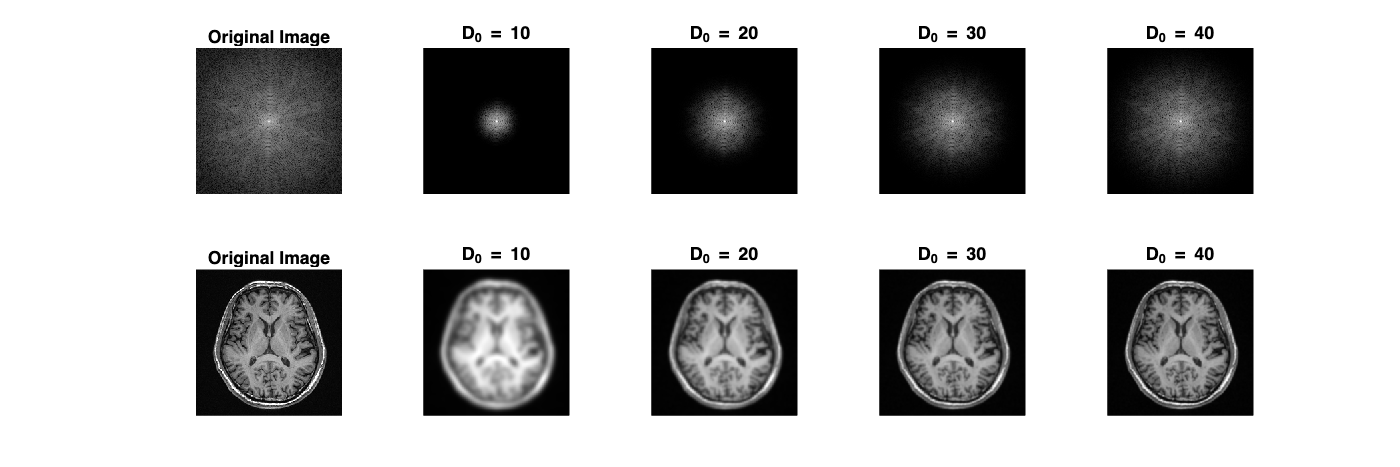

figure('Position', [100, 100, 1200, 400]);

D0_values = [10, 20, 30, 40];

% 原始图像的频域
F = fft2(mriData);
F_shifted = fftshift(F);
F_magnitude = log(1 + abs(F_shifted));

subplot(2, 5, 1);
imshow(F_magnitude, []);
title('Original Image');

subplot(2, 5, 6);
imshow(mriData, []);
title('Original Image');

% 对不同的D0值进行处理
for i = 1:length(D0_values)
    D0 = D0_values(i);
    
    % 创建高斯低通滤波器
    [M, N] = size(mriData);
    u = (-floor(M/2):ceil(M/2)-1);
    v = (-floor(N/2):ceil(N/2)-1);
    [U, V] = meshgrid(u, v);
    D = sqrt(U.^2 + V.^2);
    H = exp(-(D.^2) / (2 * D0^2));
    
    % 在频域应用滤波器
    F_filtered = F_shifted .* H;
    
    subplot(2, 5, i + 1);
    imshow(log(1 + abs(F_filtered)), []);
    title(['D_0 = ', num2str(D0)]);
    
    % 逆傅里叶变换
    F_filtered_unshifted = ifftshift(F_filtered);
    filtered_image = ifft2(F_filtered_unshifted);
    
    % 归一化处理
    filtered_image = mat2gray(real(filtered_image));
    filtered_image = uint8(filtered_image * 255);
    
    subplot(2, 5, i + 6);
    imshow(filtered_image, []);
    title(['D_0 = ', num2str(D0)]);
end     

### Step 2 加入Rician 噪声

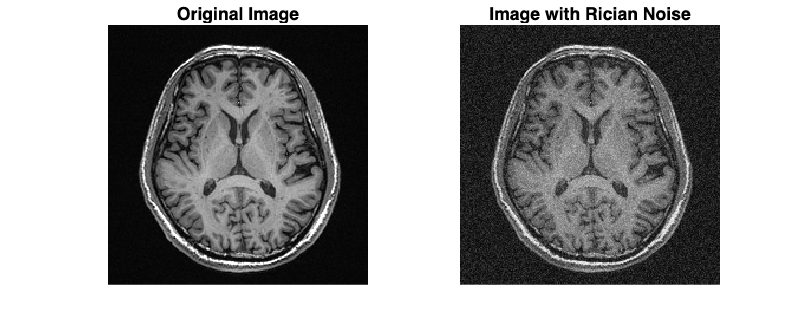

 % 定义Rician噪声的参数
nu = 0; % 信号分量
sigma = 0.1; % 噪声标准差

% 定义Rician概率密度函数
pdf_rician = @(x) (x./(sigma^2)).*exp(-(x.^2 + nu^2)./(2*sigma^2)).*besseli(0, (x.*nu)./(sigma^2));

% 找到pdf的最大值用于接受 - 拒绝采样
x_range = linspace(0, 3*sigma, 1000);
pdf_max = max(pdf_rician(x_range));

% 生成与图像大小相同的Rician噪声
noisy_shape = size(mriData);
rician_noise = zeros(noisy_shape);
for i = 1:numel(rician_noise)
    while true
        % 生成均匀分布的x和y
        x = rand() * 3*sigma;
        y = rand() * pdf_max;
        % 接受 - 拒绝准则
        if y <= pdf_rician(x)
            rician_noise(i) = x;
            break;
        end
    end
end

% 添加Rician噪声到原始图像
noisy_image = mriData + rician_noise;

% 归一化处理
noisy_image = mat2gray(noisy_image);

% 创建一个1行2列的图形窗口
figure('Position', [100, 100, 500, 200]);

% 显示原始图像
subplot(1, 2, 1);
imshow(mriData, []);
title('Original Image');

% 显示添加Rician噪声后的图像
subplot(1, 2, 2);
imshow(noisy_image, []);
title('Image with Rician Noise'); 

### Step 3 图像恢复

• Suppose the blurring kernel is known, restore the image with the following method

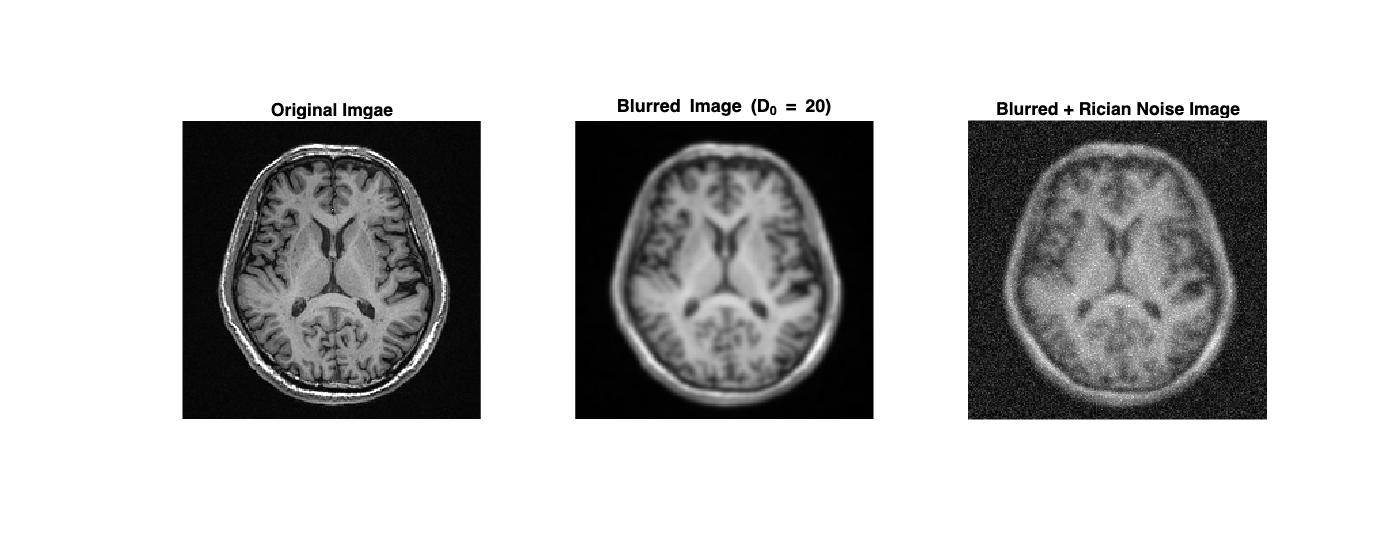

% Step 1: 频域高斯模糊（以 D0=20 为例）
D0 = 20;
[M, N] = size(mriData);
u = (-floor(M/2):ceil(M/2)-1);
v = (-floor(N/2):ceil(N/2)-1);
[U, V] = meshgrid(u, v);
D = sqrt(U.^2 + V.^2);
H = exp(-(D.^2) / (2 * D0^2)); % 高斯低通滤波器

% 频域处理
F = fft2(mriData);
F_shifted = fftshift(F);
F_filtered = F_shifted .* H;
F_filtered_unshifted = ifftshift(F_filtered);
blurred_image = ifft2(F_filtered_unshifted);
blurred_image = real(blurred_image); % 取实部（避免极小虚数干扰）

% Step 2: 添加 Rician 噪声
sigma = 0.1; % 噪声标准差
e_real = normrnd(0, sigma, size(blurred_image)); % 实部噪声
e_imag = normrnd(0, sigma, size(blurred_image)); % 虚部噪声
noisy_image = blurred_image + sqrt((0 + e_real).^2 + e_imag.^2); % nu=0 时的 Rician 噪声

% 显示结果
figure('Position', [100, 100, 1000, 400]);
subplot(1, 3, 1);
imshow(mriData, []);
title('Original Imgae');
subplot(1, 3, 2);
imshow(blurred_image, []);
title('Blurred Image (D_0 = 20)');
subplot(1, 3, 3);
imshow(noisy_image, []);
title('Blurred + Rician Noise Image');

% 计算模糊图像和含噪模糊图像的 PSNR
psnr_blurred = psnr(uint8(blurred_image * 255), uint8(mriData * 255));
psnr_noisy_blurred = psnr(uint8(noisy_image * 255), uint8(mriData * 255));
fprintf('Blurred Image (D0 = 20), PSNR: %.2f dB\n', psnr_blurred);

Blurred Image (D0 = 20), PSNR: 21.78 dB


fprintf('Blurred + Rician Noise Image, PSNR: %.2f dB\n', psnr_noisy_blurred);

Blurred + Rician Noise Image, PSNR: 15.76 dB


– Inverse filter

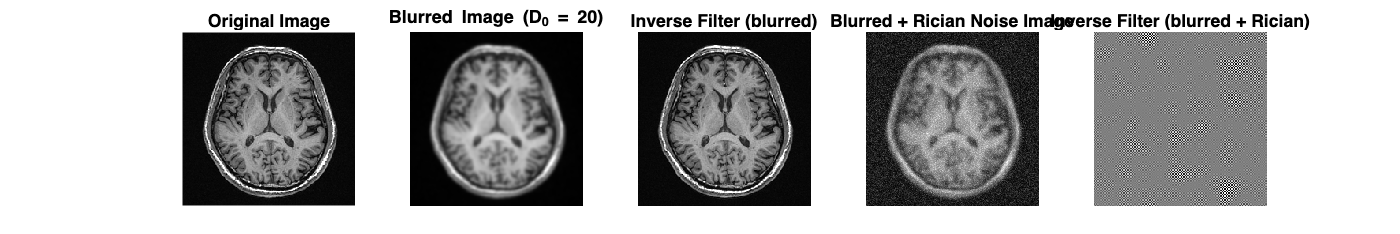

% 生成高斯低通滤波器 H
[M, N] = size(mriData);
u = (-floor(M/2):ceil(M/2)-1);
v = (-floor(N/2):ceil(N/2)-1);
[U, V] = meshgrid(u, v);
D = sqrt(U.^2 + V.^2);
D0 = 20;
H = exp(-(D.^2) / (2 * D0^2));

% 对含噪模糊图像进行傅里叶变换
F_noisy = fft2(noisy_image);
F_noisy_shifted = fftshift(F_noisy);

% 计算逆滤波器
H_inverse = 1 ./ H;
% 处理 H 中为 0 的元素，避免除零错误
H_inverse(H == 0) = 0;

% 在频域应用逆滤波器
F_restored_shifted = F_noisy_shifted .* H_inverse;

% 逆傅里叶变换
F_restored = ifftshift(F_restored_shifted);
restored_image = ifft2(F_restored);
restored_image = real(restored_image); % 取实部
restored_image = mat2gray(restored_image); % 归一化

% 对无噪声的模糊图像进行傅里叶变换
F_blurred = fft2(blurred_image);
F_blurred_shifted = fftshift(F_blurred);

% 在频域应用逆滤波器到无噪声的模糊图像
F_restored_shifted_no_noise = F_blurred_shifted .* H_inverse;

% 逆傅里叶变换
F_restored_no_noise = ifftshift(F_restored_shifted_no_noise);
restored_image_no_noise = ifft2(F_restored_no_noise);
restored_image_no_noise = real(restored_image_no_noise); % 取实部
restored_image_no_noise = mat2gray(restored_image_no_noise); % 归一化

figure('Position', [100, 100, 1200,200]);
subplot(1, 5, 1);
imshow(mriData, []);
title('Original Image');
subplot(1, 5, 2);
imshow(blurred_image, []);
title('Blurred Image (D_0 = 20)');
subplot(1, 5, 3);
imshow(restored_image_no_noise, []);
title('Inverse Filter (blurred)');
subplot(1, 5, 4);
imshow(noisy_image, []);
title('Blurred + Rician Noise Image');
subplot(1, 5, 5);
imshow(restored_image, []);
title('Inverse Filter (blurred + Rician)'); 

% 计算逆滤波恢复图像的 PSNR
psnr_inverse_no_noise = psnr(uint8(restored_image_no_noise * 255), uint8(mriData * 255));
psnr_inverse_with_noise = psnr(uint8(restored_image * 255), uint8(mriData * 255));
fprintf('Inverse Filter (blurred), PSNR: %.2f dB\n', psnr_inverse_no_noise);

Inverse Filter (blurred), PSNR: 68.47 dB


fprintf('Inverse Filter (blurred + Rician), PSNR: %.2f dB\n', psnr_inverse_with_noise);

Inverse Filter (blurred + Rician), PSNR: 8.30 dB


– Limited inverse filter

% 生成高斯低通滤波器 H
[M, N] = size(mriData);
u = (-floor(M/2):ceil(M/2)-1);
v = (-floor(N/2):ceil(N/2)-1);
[U, V] = meshgrid(u, v);
D = sqrt(U.^2 + V.^2);
D0 = 20;
H = exp(-(D.^2) / (2 * D0^2));

% 对含噪模糊图像进行傅里叶变换
F_noisy = fft2(noisy_image);
F_noisy_shifted = fftshift(F_noisy);

% 计算逆滤波器
H_inverse = 1 ./ H;
% 处理 H 中为 0 的元素，避免除零错误
H_inverse(H == 0) = 0;

% 在频域应用逆滤波器
F_restored_shifted = F_noisy_shifted .* H_inverse;

% 逆傅里叶变换
F_restored = ifftshift(F_restored_shifted);
restored_image = ifft2(F_restored);
restored_image = real(restored_image); % 取实部
restored_image = mat2gray(restored_image); % 归一化

% 对无噪声的模糊图像进行傅里叶变换
F_blurred = fft2(blurred_image);
F_blurred_shifted = fftshift(F_blurred);

% 在频域应用逆滤波器到无噪声的模糊图像
F_restored_shifted_no_noise = F_blurred_shifted .* H_inverse;

% 逆傅里叶变换
F_restored_no_noise = ifftshift(F_restored_shifted_no_noise);
restored_image_no_noise = ifft2(F_restored_no_noise);
restored_image_no_noise = real(restored_image_no_noise); % 取实部
restored_image_no_noise = mat2gray(restored_image_no_noise); % 归一化

% 有限逆滤波参数
K_values = [20, 30, 40];
restored_images_limited = cell(1, length(K_values));

for i = 1:length(K_values)
    K = K_values(i);
    % 生成有限逆滤波器
    H_limited = H;
    H_limited(D > K) = 1;
    H_limited_inverse = 1 ./ H_limited;
    H_limited_inverse(H_limited == 0) = 0;
    
    % 在频域应用有限逆滤波器
    F_restored_shifted_limited = F_noisy_shifted .* H_limited_inverse;
    
    % 逆傅里叶变换
    F_restored_limited = ifftshift(F_restored_shifted_limited);
    restored_image_limited = ifft2(F_restored_limited);
    restored_image_limited = real(restored_image_limited); % 取实部
    restored_image_limited = mat2gray(restored_image_limited); % 归一化
    
    restored_images_limited{i} = restored_image_limited;
     % 计算有限逆滤波恢复图像的 PSNR
    psnr_limited = psnr(uint8(restored_image_limited * 255), uint8(mriData * 255));
    fprintf('Limited Inverse Filter (K = %d), PSNR: %.2f dB\n', K, psnr_limited);
end

Limited Inverse Filter (K = 20), PSNR: 18.14 dB
Limited Inverse Filter (K = 30), PSNR: 18.04 dB
Limited Inverse Filter (K = 40), PSNR: 15.34 dB


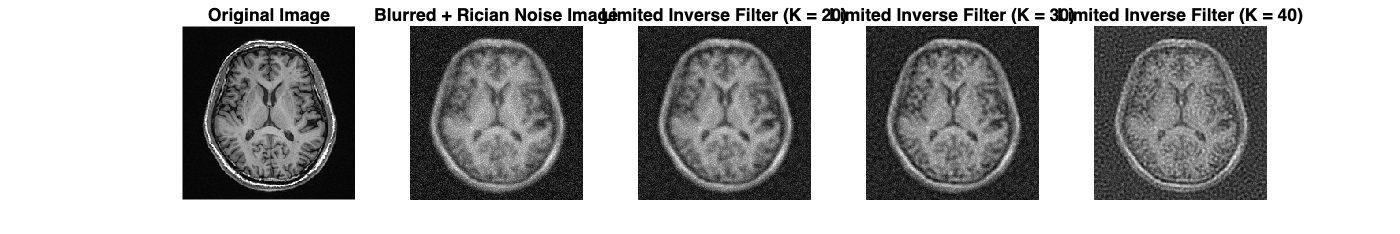


% 显示结果
figure('Position', [100, 100, 1200, 200]);
subplot(1, 5, 1);
imshow(mriData, []);
title('Original Image');
subplot(1, 5, 2);
imshow(noisy_image, []);
title('Blurred + Rician Noise Image');
for i = 1:length(K_values)
    subplot(1, 5, i + 2);
    imshow(restored_images_limited{i}, []);
    title(['Limited Inverse Filter (K = ', num2str(K_values(i)), ')']);
end    

– Wiener filter 

% 生成高斯低通滤波器 H
[M, N] = size(mriData);
u = (-floor(M/2):ceil(M/2)-1);
v = (-floor(N/2):ceil(N/2)-1);
[U, V] = meshgrid(u, v);
D = sqrt(U.^2 + V.^2);
D0 = 20;
H = exp(-(D.^2) / (2 * D0^2));

% 对含噪模糊图像进行傅里叶变换
F_noisy = fft2(noisy_image);
F_noisy_shifted = fftshift(F_noisy);

% 计算逆滤波器
H_inverse = 1 ./ H;
% 处理 H 中为 0 的元素，避免除零错误
H_inverse(H == 0) = 0;

% 在频域应用逆滤波器
F_restored_shifted = F_noisy_shifted .* H_inverse;

% 逆傅里叶变换
F_restored = ifftshift(F_restored_shifted);
restored_image = ifft2(F_restored);
restored_image = real(restored_image); % 取实部
restored_image = mat2gray(restored_image); % 归一化

% 对无噪声的模糊图像进行傅里叶变换
F_blurred = fft2(blurred_image);
F_blurred_shifted = fftshift(F_blurred);

% 在频域应用逆滤波器到无噪声的模糊图像
F_restored_shifted_no_noise = F_blurred_shifted .* H_inverse;

% 逆傅里叶变换
F_restored_no_noise = ifftshift(F_restored_shifted_no_noise);
restored_image_no_noise = ifft2(F_restored_no_noise);
restored_image_no_noise = real(restored_image_no_noise); % 取实部
restored_image_no_noise = mat2gray(restored_image_no_noise); % 归一化

% 有限逆滤波参数
K_values = [20, 30, 40];
restored_images_limited = cell(1, length(K_values));

for i = 1:length(K_values)
    K = K_values(i);
    % 生成有限逆滤波器
    H_limited = H;
    H_limited(D > K) = 1;
    H_limited_inverse = 1 ./ H_limited;
    H_limited_inverse(H_limited == 0) = 0;
    
    % 在频域应用有限逆滤波器
    F_restored_shifted_limited = F_noisy_shifted .* H_limited_inverse;
    
    % 逆傅里叶变换
    F_restored_limited = ifftshift(F_restored_shifted_limited);
    restored_image_limited = ifft2(F_restored_limited);
    restored_image_limited = real(restored_image_limited); % 取实部
    restored_image_limited = mat2gray(restored_image_limited); % 归一化
    
    restored_images_limited{i} = restored_image_limited;
end

% 维纳滤波参数
K_wiener_values = [0.0025, 0.05, 0.1, 1];
restored_images_wiener = cell(1, length(K_wiener_values));

for i = 1:length(K_wiener_values)
    K_wiener = K_wiener_values(i);
    % 生成维纳滤波器
    H_wiener = conj(H) ./ (abs(H).^2 + K_wiener);
    
    % 在频域应用维纳滤波器
    F_restored_shifted_wiener = F_noisy_shifted .* H_wiener;
    
    % 逆傅里叶变换
    F_restored_wiener = ifftshift(F_restored_shifted_wiener);
    restored_image_wiener = ifft2(F_restored_wiener);
    restored_image_wiener = real(restored_image_wiener); % 取实部
    restored_image_wiener = mat2gray(restored_image_wiener); % 归一化
    
    restored_images_wiener{i} = restored_image_wiener;
     % 计算维纳滤波恢复图像的 PSNR
    psnr_wiener = psnr(uint8(restored_image_wiener * 255), uint8(mriData * 255));
    fprintf('Wiener Filter (K = %.4f), PSNR: %.2f dB\n', K_wiener, psnr_wiener);
end

Wiener Filter (K = 0.0025), PSNR: 11.25 dB
Wiener Filter (K = 0.0500), PSNR: 18.10 dB
Wiener Filter (K = 0.1000), PSNR: 19.39 dB
Wiener Filter (K = 1.0000), PSNR: 18.59 dB


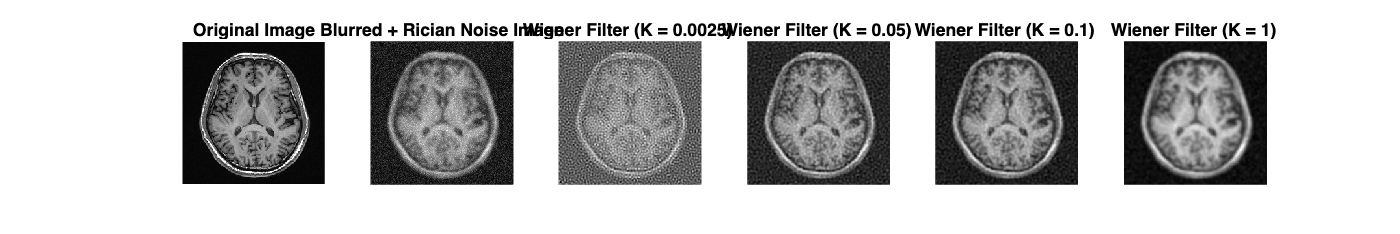


% 显示结果
figure('Position', [100, 100, 1800, 300]);
subplot(1, 6, 1);
imshow(mriData, []);
title('Original Image');
subplot(1, 6, 2);
imshow(noisy_image, []);
title('Blurred + Rician Noise Image');
for i = 1:length(K_wiener_values)
    subplot(1, 6, i + 2);
    imshow(restored_images_wiener{i}, []);
    title(['Wiener Filter (K = ', num2str(K_wiener_values(i)), ') ']);
end    

### Step 4: 使用 NLM 方法对 Rician 噪声去噪

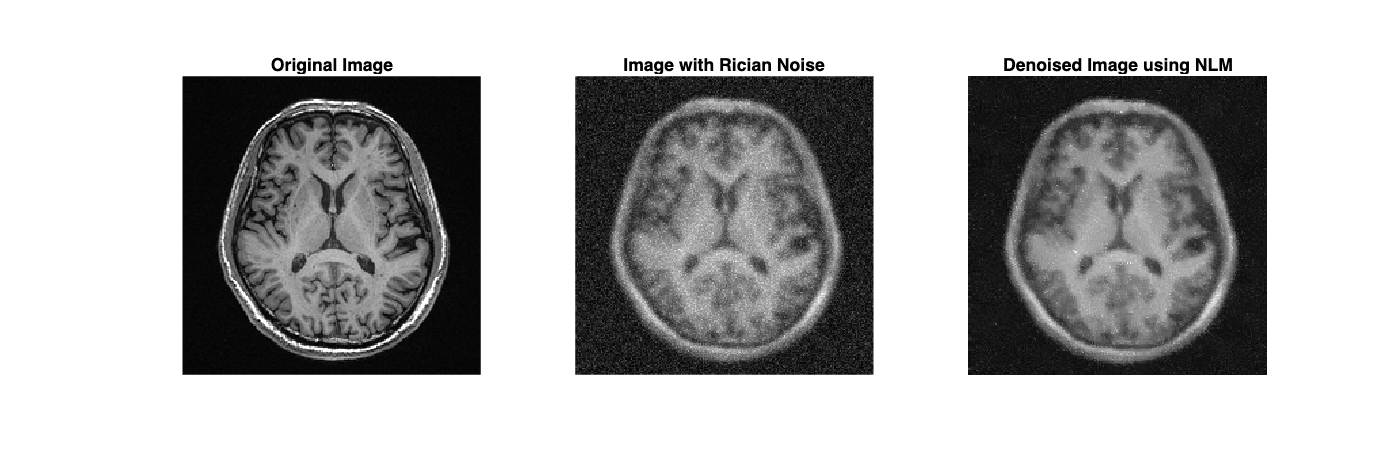

patch_size = 3; % 补丁大小
search_size = 15; % 搜索窗口大小
h = 0.05; % 相似度阈值

denoised_image = nlm_rician(noisy_image, patch_size, search_size, h);

% 显示原始图、加了噪声后的图和去噪后的结果图
figure('Position', [100, 100, 1500, 500]);
subplot(1, 3, 1);
imshow(mriData, []);
title('Original Image');

subplot(1, 3, 2);
imshow(noisy_image, []);
title('Image with Rician Noise');

subplot(1, 3, 3);
imshow(denoised_image, []);
title('Denoised Image using NLM');


% 计算 NLM 去噪后的 PSNR
psnr_nlm = psnr(uint8(denoised_image * 255), uint8(mriData * 255));
fprintf('NLM Denoised Image, PSNR: %.2f dB\n', psnr_nlm);

NLM Denoised Image, PSNR: 16.02 dB



function denoised = nlm_rician(noisy_image, patch_size, search_size, h)
    [rows, cols] = size(noisy_image);
    denoised = zeros(rows, cols);
    pad_size = floor(patch_size/2);
    noisy_pad = padarray(noisy_image, [pad_size pad_size], 'symmetric');
    
    for i = 1:rows
        for j = 1:cols
            % 中心补丁
            x1 = i; y1 = j;
            patch_center = noisy_pad(x1:x1+patch_size-1, y1:y1+patch_size-1);
            
            % 搜索窗口
            search_x1 = max(i - floor(search_size/2), 1);
            search_x2 = min(i + floor(search_size/2), rows);
            search_y1 = max(j - floor(search_size/2), 1);
            search_y2 = min(j + floor(search_size/2), cols);
            
            % 计算所有候选补丁的权重
            weights = zeros(search_x2 - search_x1 + 1, search_y2 - search_y1 + 1);
            for dx = search_x1:search_x2
                for dy = search_y1:search_y2
                    % 确保索引不超出边界
                    patch_x1 = dx;
                    patch_x2 = min(dx + patch_size - 1, size(noisy_pad, 1));
                    patch_y1 = dy;
                    patch_y2 = min(dy + patch_size - 1, size(noisy_pad, 2));
                    patch_candidate = noisy_pad(patch_x1:patch_x2, patch_y1:patch_y2);
                    % 调整补丁大小以匹配中心补丁
                    if size(patch_candidate, 1) < patch_size || size(patch_candidate, 2) < patch_size
                        patch_candidate = padarray(patch_candidate, [patch_size - size(patch_candidate, 1), patch_size - size(patch_candidate, 2)], 0, 'post');
                    end
                    distance = sum((patch_center - patch_candidate).^2, 'all');
                    weights(dx - search_x1 + 1, dy - search_y1 + 1) = exp(-distance / (h^2 * numel(patch_center)));
                end
            end
            % 归一化权重并计算均值
            weights = weights / sum(weights(:));
            denoised(i,j) = sum(noisy_pad(search_x1:search_x2, search_y1:search_y2) .* weights, 'all');
        end
    end
end    